%% Degree 1
clear
eDegree = 1;
bFun = basisFunction("Lagrange",eDegree,sym('x','real'))

bFun = struct with fields:
       name: "Lagrange"
     degree: 1
    variate: [1×1 sym]
     domain: [-1 1]
      nodes: [-1 1]
      basis: [2×1 sym]


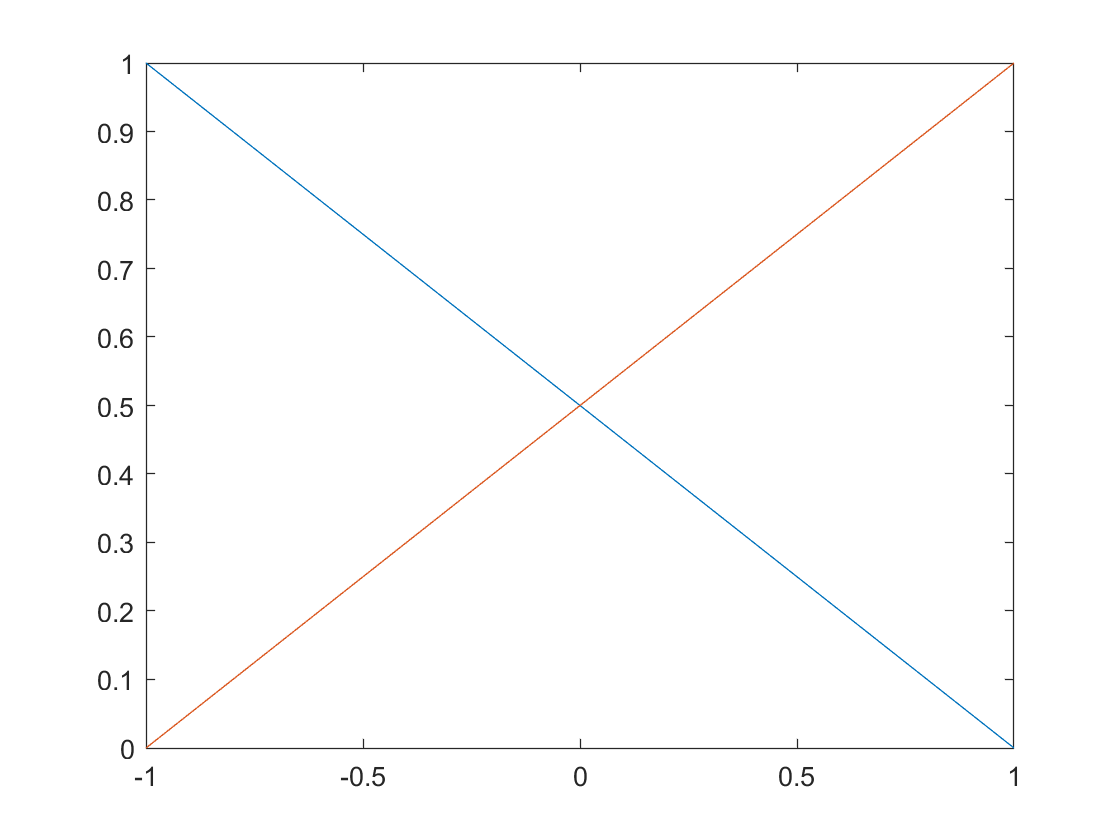

fplot(bFun.basis,bFun.domain)

bFun_indefIntegral = int(bFun.basis)

$$bFun\_indefIntegral = \left(\begin{array}{c} -\frac{x\,\left(x-2\right)}{4}\\ \frac{x\,\left(x+2\right)}{4} \end{array}\right)$$

bFun_defIntegral = int(bFun.basis,bFun.domain)

$$bFun\_defIntegral = \left(\begin{array}{c} 1\\ 1 \end{array}\right)$$

% Do inner products of <Ni|Nj>, i,j = 1:2
for ii = 1:length(bFun.basis)
    for jj = 1:length(bFun.basis)
        InnerProduct(ii,jj) = int(bFun.basis(ii) * bFun.basis(jj));
    end
end
disp(InnerProduct)

$$\left(\begin{array}{cc} \frac{{\left(x-1\right)}^{3}}{12} & -\frac{x\,\left(x^{2}-3\right)}{12}\\ -\frac{x\,\left(x^{2}-3\right)}{12} & \frac{{\left(x+1\right)}^{3}}{12} \end{array}\right)$$

clear
eDegree = 2;
bFun = basisFunction("Lagrange",eDegree,sym('x','real'))

bFun = struct with fields:
       name: "Lagrange"
     degree: 2
    variate: [1×1 sym]
     domain: [-1 1]
      nodes: [-1 0 1]
      basis: [3×1 sym]


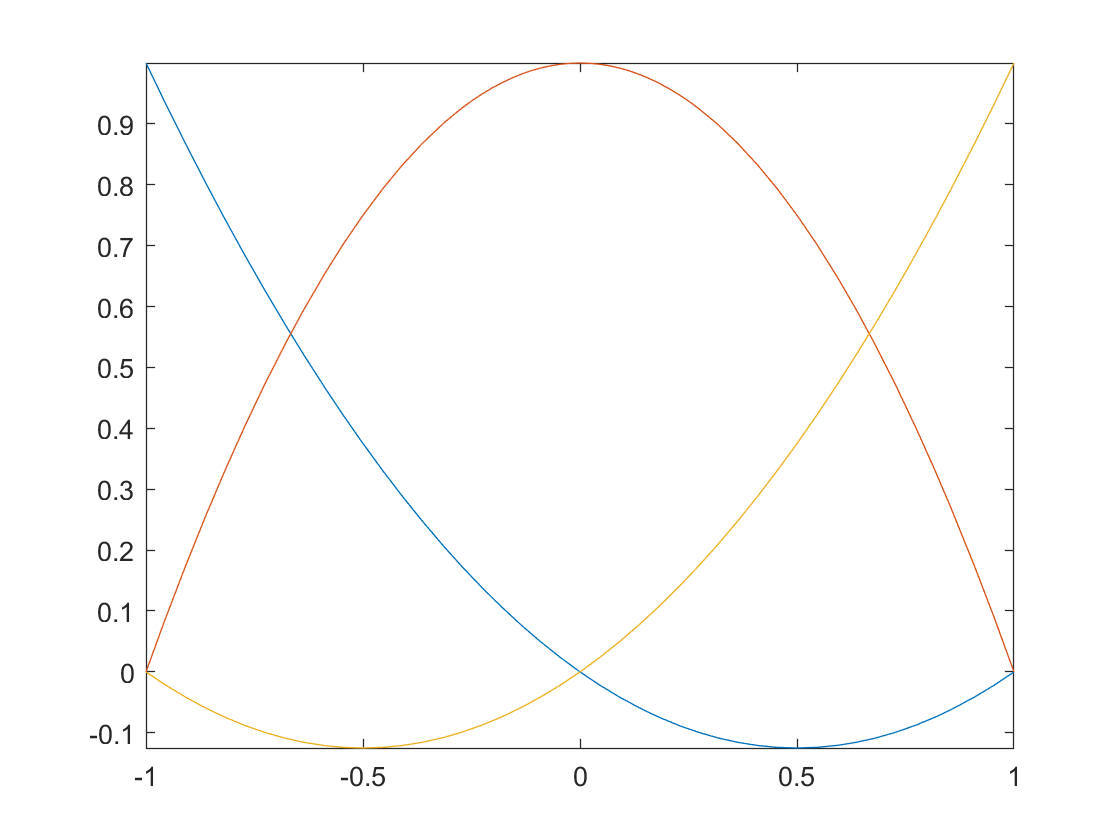

fplot(bFun.basis,bFun.domain)

bFun_indefIntegral = int(bFun.basis)

$$bFun\_indefIntegral = \left(\begin{array}{c} \frac{x^{2}\,\left(2\,x-3\right)}{12}\\ -\frac{x\,\left(x^{2}-3\right)}{3}\\ \frac{x^{2}\,\left(2\,x+3\right)}{12} \end{array}\right)$$

bFun_defIntegral = int(bFun.basis,bFun.domain)

$$bFun\_defIntegral = \left(\begin{array}{c} \frac{1}{3}\\ \frac{4}{3}\\ \frac{1}{3} \end{array}\right)$$

% Do inner products of <Ni|Nj>, i,j = 1:3
for ii = 1:length(bFun.basis)
    for jj = 1:length(bFun.basis)
        InnerProduct(ii,jj) = int(bFun.basis(ii) * bFun.basis(jj));
    end
end
disp(InnerProduct)

$$\left(\begin{array}{ccc} \frac{x^{3}\,\left(6\,x^{2}-15\,x+10\right)}{120} & -\frac{x^{5}}{10}+\frac{x^{4}}{8}+\frac{x^{3}}{6}-\frac{x^{2}}{4} & \frac{x^{3}\,\left(3\,x^{2}-5\right)}{60}\\ -\frac{x^{5}}{10}+\frac{x^{4}}{8}+\frac{x^{3}}{6}-\frac{x^{2}}{4} & \frac{x^{5}}{5}-\frac{2\,x^{3}}{3}+x & -\frac{x^{5}}{10}-\frac{x^{4}}{8}+\frac{x^{3}}{6}+\frac{x^{2}}{4}\\ \frac{x^{3}\,\left(3\,x^{2}-5\right)}{60} & -\frac{x^{5}}{10}-\frac{x^{4}}{8}+\frac{x^{3}}{6}+\frac{x^{2}}{4} & \frac{x^{3}\,\left(6\,x^{2}+15\,x+10\right)}{120} \end{array}\right)$$

% Simplify the inner product functions
simplify(InnerProduct)

$$ans = \left(\begin{array}{ccc} \frac{x^{3}\,\left(6\,x^{2}-15\,x+10\right)}{120} & \frac{x^{2}\,\left(-12\,x^{3}+15\,x^{2}+20\,x-30\right)}{120} & \frac{x^{3}\,\left(3\,x^{2}-5\right)}{60}\\ \frac{x^{2}\,\left(-12\,x^{3}+15\,x^{2}+20\,x-30\right)}{120} & \frac{x^{5}}{5}-\frac{2\,x^{3}}{3}+x & \frac{x^{2}\,\left(-12\,x^{3}-15\,x^{2}+20\,x+30\right)}{120}\\ \frac{x^{3}\,\left(3\,x^{2}-5\right)}{60} & \frac{x^{2}\,\left(-12\,x^{3}-15\,x^{2}+20\,x+30\right)}{120} & \frac{x^{3}\,\left(6\,x^{2}+15\,x+10\right)}{120} \end{array}\right)$$

% Expand the inner product functions
expand(InnerProduct)

$$ans = \left(\begin{array}{ccc} \frac{x^{5}}{20}-\frac{x^{4}}{8}+\frac{x^{3}}{12} & -\frac{x^{5}}{10}+\frac{x^{4}}{8}+\frac{x^{3}}{6}-\frac{x^{2}}{4} & \frac{x^{5}}{20}-\frac{x^{3}}{12}\\ -\frac{x^{5}}{10}+\frac{x^{4}}{8}+\frac{x^{3}}{6}-\frac{x^{2}}{4} & \frac{x^{5}}{5}-\frac{2\,x^{3}}{3}+x & -\frac{x^{5}}{10}-\frac{x^{4}}{8}+\frac{x^{3}}{6}+\frac{x^{2}}{4}\\ \frac{x^{5}}{20}-\frac{x^{3}}{12} & -\frac{x^{5}}{10}-\frac{x^{4}}{8}+\frac{x^{3}}{6}+\frac{x^{2}}{4} & \frac{x^{5}}{20}+\frac{x^{4}}{8}+\frac{x^{3}}{12} \end{array}\right)$$

% Evaluate the functions at some value: x = 2
subs(simplify(InnerProduct),bFun.variate,2)

$$ans = \left(\begin{array}{ccc} \frac{4}{15} & -\frac{13}{15} & \frac{14}{15}\\ -\frac{13}{15} & \frac{46}{15} & -\frac{43}{15}\\ \frac{14}{15} & -\frac{43}{15} & \frac{64}{15} \end{array}\right)$$

% Evaluate performance of symbolic substitution
InnerProduct = simplify(InnerProduct);
f = @() subs(InnerProduct,bFun.variate,2) % Creates an anonymous symbolic function

f = function_handle with value:
    @()subs(InnerProduct,bFun.variate,2)


elapsedTime = timeit(f);
disp("Symbolic substitution took: " + num2str(elapsedTime) + " Seconds")

Symbolic substitution took: 0.008065 Seconds


% Create a "Matlab Function" from the equations:
mFun = matlabFunction(InnerProduct) % Creates an anonymous, vectorized, double-precision function

mFun = function_handle with value:
    @(x)reshape([(x.^3.*(x.*-1.5e+1+x.^2.*6.0+1.0e+1))./1.2e+2,(x.^2.*(x.*2.0e+1+x.^2.*1.5e+1-x.^3.*1.2e+1-3.0e+1))./1.2e+2,(x.^3.*(x.^2.*3.0-5.0))./6.0e+1,(x.^2.*(x.*2.0e+1+x.^2.*1.5e+1-x.^3.*1.2e+1-3.0e+1))./1.2e+2,x-x.^3.*(2.0./3.0)+x.^5./5.0,(x.^2.*(x.*2.0e+1-x.^2.*1.5e+1-x.^3.*1.2e+1+3.0e+1))./1.2e+2,(x.^3.*(x.^2.*3.0-5.0))./6.0e+1,(x.^2.*(x.*2.0e+1-x.^2.*1.5e+1-x.^3.*1.2e+1+3.0e+1))./1.2e+2,(x.^3.*(x.*1.5e+1+x.^2.*6.0+1.0e+1))./1.2e+2],[3,3])


f1 = @() matlabFunction(InnerProduct)

f1 = function_handle with value:
    @()matlabFunction(InnerProduct)


elapsedTime_1 = timeit(f1);
disp("matlabFunction evaluation took: " + num2str(elapsedTime_1) + " Seconds")

matlabFunction evaluation took: 0.029778 Seconds



f2 = @() mFun(2) % Creates an anonymous function handle (for purposes of benchmarking only)

f2 = function_handle with value:
    @()mFun(2)


elapsedTime_2 = timeit(f2);
disp("Evaluating output of matlabFunction took: " + num2str(elapsedTime_2) + " Seconds")

Evaluating output of matlabFunction took: 1.5989e-06 Seconds
